# Broken Rotor Fault Detection in AC Induction Motors Using Vibration and Electrical Signals

This example shows how to detect failures in an AC induction motor. Typically, AC motors are driven by a three-phase power converter or an industrial power supply. Failures in the rotor bars of the motor can present themselves in various electrical and vibration signals collected from the system, including voltages and currents of each of the three phases and the acceleration and velocity signals in radial, axial, and tangential directions. Here, you use some of these signals in the **Diagnostic Feature Designer** app to extract features, which you then use to identify the number of broken rotor bars in the motor.

## Data Set

The experimental workbench consists of a three-phase induction motor coupled with a direct-current machine, which works as a generator simulating the load torque, connected by a shaft containing a rotating torque meter. For more details about the workbench setup, see [IEEE Broken Rotor Bar Database](https://ieee-dataport.org/open-access/experimental-database-detecting-and-diagnosing-rotor-broken-bar-three-phase-induction).

The data set contains electrical and mechanical signals from experiments on three-phase induction motors, using the experimental setup shown in the figure.

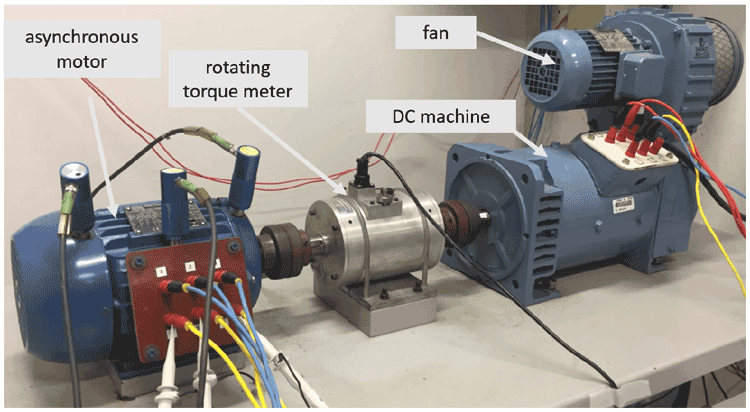

Electrical and vibration signals were collected from the system under the following health and loading conditions:

- 0, 1, 2, 3, and 4 broken rotor bars as the health condition

- 0.5, 1.0, 1.5, 2.0, 2.5, 3.0, 3.5, and 4.0 Nm torque as the load condition

Ten experiments were performed for each combination of health and loading condition. The following signals were acquired during each experiment:

- Voltage of each phase ($V_a$, $V_b$, $V_c$)

- Current draw of each phase ($I_a$, $I_b$, $I_c$)

- Mechanical vibration speeds tangential to the housing (${\textrm{Vib}}_{\;\textrm{carc}}$) and base (${\textrm{Vib}}_{\;\textrm{base}}$)

- Mechanical vibration speed axial on the driven side (${\textrm{Vib}}_{\;\textrm{axial}}$)

- Mechanical vibration speeds radial on the driven side (${\textrm{Vib}}_{\;\textrm{acpi}}$) and nondriven side (${\textrm{Vib}}_{\;\textrm{acpe}}$).

For the full data set, visit [IEEE Broken Rotor Bar Database](https://ieee-dataport.org/open-access/experimental-database-detecting-and-diagnosing-rotor-broken-bar-three-phase-induction), download the entire repository as a ZIP file, and save it in the same directory as this Live Script.

% Remove this comment when using the original data set.
filename = "banco de dados experimental.zip";

Alternatively, you can use a reduced data set from the [MathWorks repository](https://ssd.mathworks.com/supportfiles/predmaint/broken-rotor-bar-fault-data/experimental_database_short.zip). This data set contains two experiments per operating condition.

% Comment out this section when using the original data set.
% filename = "experimental_database_short.zip";
% if ~exist(filename,'file')
%  url = "https://ssd.mathworks.com/supportfiles/predmaint/broken-rotor-bar-fault-data/" + filename;
%  websave(filename,url);
%end

Extract the compressed data files into the current folder.

unzip(filename)

## Extract Ensemble Member Data

Convert the original motor data files into individual ensemble member data files for all combinations of health condition, load torque, and experiment index. The files are saved to a target folder and used by the `fileEnsembleDatastore` object in the **Diagnostic Feature Designer** app for data processing and feature extraction.

You can change the amount of experiments per operating condition to use in the ensemble data. If you use the reduced data set, use two experiments; otherwise, you can use up to 10.

numExperiments = 10; % Up to a maximum of 10 if using the original data set

The unzipped files of the original data set are associated with different numbers of broken rotor bars. Create bookkeeping variables to associate the original data files with the corresponding number of broken rotor bars.

% Names of the original data files restored from the zip archive.
files = [ ...
  "struct_rs_R1.mat", ...
  "struct_r1b_R1.mat", ...
  "struct_r2b_R1.mat", ...
  "struct_r3b_R1.mat", ...
  "struct_r4b_R1.mat", ...
  ];

% Rotor conditions (that is, number of broken bars) corresponding to original data files.
health = [
  "healthy", ...
  "broken_bar_1", ...
  "broken_bar_2", ...
  "broken_bar_3", ...
  "broken_bar_4", ...
  ];

Fs_vib = 7600; % Sampling frequency of vibration signals in Hz.
Fs_elec = 50000; % Sampling frequency of electrical signals in Hz.

Create a target folder to store the ensemble member data files that you generate next.

folder = 'data_files';
if ~exist(folder, 'dir')
  mkdir(folder);
end

Iterate over the original data files, where each file corresponds to a given number of broken rotor bars, and construct individual ensemble member data files for each combination of load and number of broken rotor bars.

% Iterate over the number of broken rotor bars.
for i = 1:numel(health)
  fprintf('Processing data file %s\n', files(i))

  % Load the original data set stored as a struct.
  S = load(files(i));
  fields = fieldnames(S);
  dataset = S.(fields{1});

  loadLevels = fieldnames(dataset);
  % Iterate over load (torque) levels in each data set.
  for j = 1:numel(loadLevels)
    experiments = dataset.(loadLevels{j});
    data = struct;

    % Iterate over the given number of experiments for each load level.
    for k = 1:numExperiments
      signalNames = fieldnames(experiments(k));
      % Iterate over the signals in each experimental data set.
      for l = 1:numel(signalNames)
        % Experimental (electrical and vibration) data
        data.(signalNames{l}) = experiments(k).(signalNames{l});
      end

      % Operating conditions
      data.Health = health(i);
      data.Load = string(loadLevels{j});

      % Constant parameters
      data.Fs_vib = Fs_vib;
      data.Fs_elec = Fs_elec;

      % Save memberwise data.
      name = sprintf('rotor%db_%s_experiment%02d',  i-1, loadLevels{j}, k);
      fprintf('\tCreating the member data file %s.mat\n', name)
      filename = fullfile(pwd, folder, name);
      save(filename, '-v7.3', '-struct', 'data'); % Save fields as individual variables.
    end
  end
end

Processing data file struct_rs_R1.mat


	Creating the member data file rotor0b_torque05_experiment01.mat
	Creating the member data file rotor0b_torque05_experiment02.mat
	Creating the member data file rotor0b_torque05_experiment03.mat
	Creating the member data file rotor0b_torque05_experiment04.mat
	Creating the member data file rotor0b_torque05_experiment05.mat
	Creating the member data file rotor0b_torque05_experiment06.mat
	Creating the member data file rotor0b_torque05_experiment07.mat
	Creating the member data file rotor0b_torque05_experiment08.mat
	Creating the member data file rotor0b_torque05_experiment09.mat
	Creating the member data file rotor0b_torque05_experiment10.mat
	Creating the member data file rotor0b_torque10_experiment01.mat
	Creating the member data file rotor0b_torque10_experiment02.mat
	Creating the member data file rotor0b_torque10_experiment03.mat
	Creating the member data file rotor0b_torque10_experiment04.mat
	Creating the member data file rotor0b_torque10_experiment05.mat
	Creating the member data

Processing data file struct_r1b_R1.mat


	Creating the member data file rotor1b_torque05_experiment01.mat
	Creating the member data file rotor1b_torque05_experiment02.mat
	Creating the member data file rotor1b_torque05_experiment03.mat
	Creating the member data file rotor1b_torque05_experiment04.mat
	Creating the member data file rotor1b_torque05_experiment05.mat
	Creating the member data file rotor1b_torque05_experiment06.mat
	Creating the member data file rotor1b_torque05_experiment07.mat
	Creating the member data file rotor1b_torque05_experiment08.mat
	Creating the member data file rotor1b_torque05_experiment09.mat
	Creating the member data file rotor1b_torque05_experiment10.mat
	Creating the member data file rotor1b_torque10_experiment01.mat
	Creating the member data file rotor1b_torque10_experiment02.mat
	Creating the member data file rotor1b_torque10_experiment03.mat
	Creating the member data file rotor1b_torque10_experiment04.mat
	Creating the member data file rotor1b_torque10_experiment05.mat
	Creating the member data

Processing data file struct_r2b_R1.mat


	Creating the member data file rotor2b_torque05_experiment01.mat
	Creating the member data file rotor2b_torque05_experiment02.mat
	Creating the member data file rotor2b_torque05_experiment03.mat
	Creating the member data file rotor2b_torque05_experiment04.mat
	Creating the member data file rotor2b_torque05_experiment05.mat
	Creating the member data file rotor2b_torque05_experiment06.mat
	Creating the member data file rotor2b_torque05_experiment07.mat
	Creating the member data file rotor2b_torque05_experiment08.mat
	Creating the member data file rotor2b_torque05_experiment09.mat
	Creating the member data file rotor2b_torque05_experiment10.mat
	Creating the member data file rotor2b_torque10_experiment01.mat
	Creating the member data file rotor2b_torque10_experiment02.mat
	Creating the member data file rotor2b_torque10_experiment03.mat
	Creating the member data file rotor2b_torque10_experiment04.mat
	Creating the member data file rotor2b_torque10_experiment05.mat
	Creating the member data

Processing data file struct_r3b_R1.mat


	Creating the member data file rotor3b_torque05_experiment01.mat
	Creating the member data file rotor3b_torque05_experiment02.mat
	Creating the member data file rotor3b_torque05_experiment03.mat
	Creating the member data file rotor3b_torque05_experiment04.mat
	Creating the member data file rotor3b_torque05_experiment05.mat
	Creating the member data file rotor3b_torque05_experiment06.mat
	Creating the member data file rotor3b_torque05_experiment07.mat
	Creating the member data file rotor3b_torque05_experiment08.mat
	Creating the member data file rotor3b_torque05_experiment09.mat
	Creating the member data file rotor3b_torque05_experiment10.mat
	Creating the member data file rotor3b_torque10_experiment01.mat
	Creating the member data file rotor3b_torque10_experiment02.mat
	Creating the member data file rotor3b_torque10_experiment03.mat
	Creating the member data file rotor3b_torque10_experiment04.mat
	Creating the member data file rotor3b_torque10_experiment05.mat
	Creating the member data

Processing data file struct_r4b_R1.mat


	Creating the member data file rotor4b_torque05_experiment01.mat
	Creating the member data file rotor4b_torque05_experiment02.mat
	Creating the member data file rotor4b_torque05_experiment03.mat
	Creating the member data file rotor4b_torque05_experiment04.mat
	Creating the member data file rotor4b_torque05_experiment05.mat
	Creating the member data file rotor4b_torque05_experiment06.mat
	Creating the member data file rotor4b_torque05_experiment07.mat
	Creating the member data file rotor4b_torque05_experiment08.mat
	Creating the member data file rotor4b_torque05_experiment09.mat
	Creating the member data file rotor4b_torque05_experiment10.mat
	Creating the member data file rotor4b_torque10_experiment01.mat
	Creating the member data file rotor4b_torque10_experiment02.mat
	Creating the member data file rotor4b_torque10_experiment03.mat
	Creating the member data file rotor4b_torque10_experiment04.mat
	Creating the member data file rotor4b_torque10_experiment05.mat
	Creating the member data

## Construct File Ensemble Datastore

Create a file ensemble datastore for the data stored in the MAT-files, and configure it with functions that interact with the software to read from and write to the datastore.

location = fullfile(pwd, folder);
ens = fileEnsembleDatastore(location,'.mat');

Before you can interact with data in the ensemble, you must create functions that tell the software how to process the data files to read variables into the MATLAB workspace and to write data back to the files. For this example, use the following supplied functions.

- `readMemberData` — Extract requested variables stored in the file. The function returns a table row containing one table variable for each requested variable.  

- `writeMemberData` — Take a structure and write its variables to a data file as individual stored variables. 

ens.ReadFcn = @readMemberData;
ens.WriteToMemberFcn = @writeMemberData;

Finally, set properties of the ensemble to identify data variables, condition variables, and the variables selected to read. These variables include ones that are not in the original data set but rather specified and constructed by `readMemberData`: `Vib_acpi_env`, the band-pass filtered radial vibration signal, and `Ia_env_ps`, the band-pass filtered envelope spectrum of the first-phase current signal. **Diagnostic Feature Designer** can read synthetic signals such as these as well.

ens.DataVariables = [...
  "Va"; "Vb"; "Vc"; "Ia"; "Ib"; "Ic"; ...
  "Vib_acpi"; "Vib_carc"; "Vib_acpe"; "Vib_axial"; "Vib_base"; "Trigger"];
ens.ConditionVariables = ["Health"; "Load"];
ens.SelectedVariables = ["Ia"; "Vib_acpi"; "Health"; "Load"];

% Add synthetic signals and spectra generated directly in the readMemberData
% function.
ens.DataVariables = [ens.DataVariables; "Vib_acpi_env"; "Ia_env_ps"];
ens.SelectedVariables = [ens.SelectedVariables; "Vib_acpi_env"; "Ia_env_ps"];

Examine the ensemble. The functions and the variable names are assigned to the appropriate properties.

ens

ens =   fileEnsembleDatastore with properties:

                 ReadFcn: @readMemberData
        WriteToMemberFcn: @writeMemberData
           DataVariables: [14×1 string]
    IndependentVariables: [0×0 string]
      ConditionVariables: [2×1 string]
       SelectedVariables: [6×1 string]
                ReadSize: 1
              NumMembers: 400
          LastMemberRead: [0×0 string]
                   Files: [400×1 string]


Examine a member of the ensemble and confirm that the desired variables are read or generated.

T = read(ens)

T = 1×6 table
            Ia                  Vib_acpi            Vib_acpi_env          Ia_env_ps         Health         Load   
    ___________________    __________________    __________________    ________________    _________    __________

    {50001×1 timetable}    {7601×1 timetable}    {7601×1 timetable}    {25001×2 double}    "healthy"    "torque05"


From the power spectrum of one of the vibration signals, `Vib_acpi`, observe that there are frequency components of interest in the [900 1300] Hz region. These components are a primary reason why you use `readMemberData` to compute the band-pass filtered variables - `Vib_acpi_env` and `Ia_env_ps`.

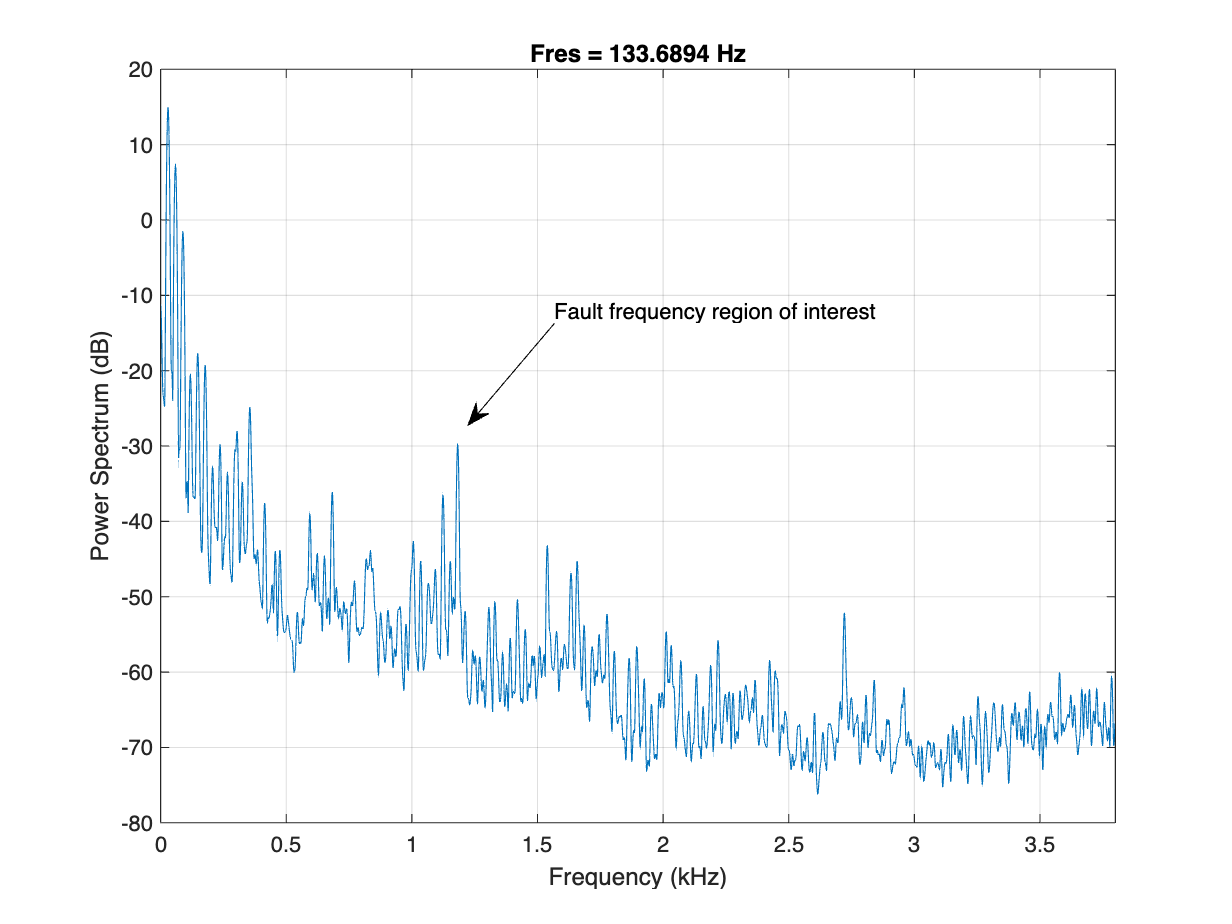

% Power spectrum of vibration signal, Vib_acpi
vib = T.Vib_acpi{1};
pspectrum(vib.Data, Fs_vib);
annotation("textarrow", [0.45 0.38], [0.65 0.54], "String", "Fault frequency region of interest")% Power spectrum of vibration signal, Vib_acpi

vib = T.Vib_acpi{1};
pspectrum(vib.Data, Fs_vib);

annotation("textarrow", [0.45 0.38], [0.65 0.54], "String", "Fault frequency region of interest")

The envelope of signals after band-pass filtering them can help reveal demodulated signals containing behavior related to the health of the system.

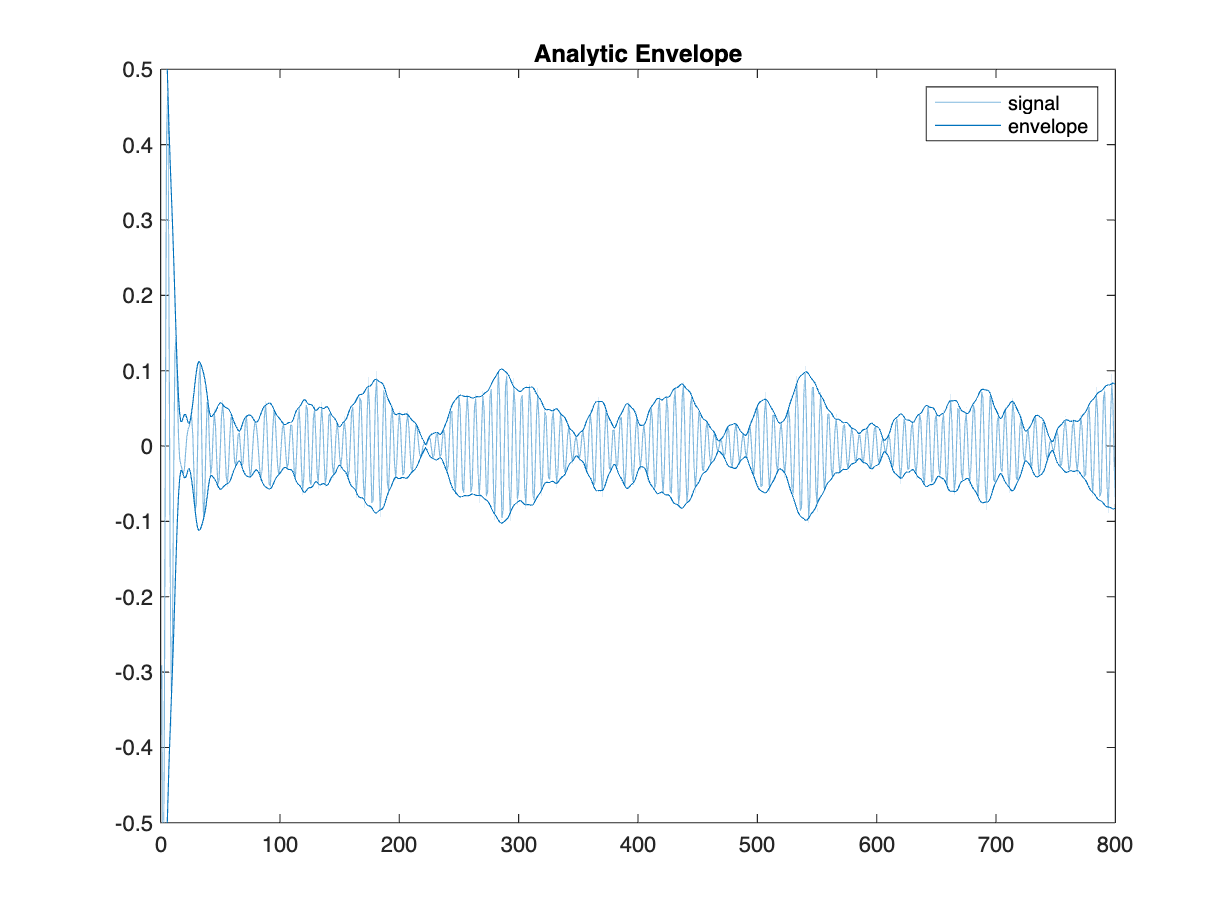

% Envelop of vibration signal
y = bandpass(vib.Data, [900 1300], Fs_vib);
envelope(y)
axis([0 800 -0.5 0.5])

% Specify variables to read
ens.SelectedVariables = ["Vib_acpi_env", "Health"];

% Read all data into a table
T = readall(ens);

numTrainFiles = 750;
[ensTrain,ensValidation] = splitEachLabel(ens,numTrainFiles,"randomize");

Incorrect number or types of inputs or outputs for function splitEachLabel.

layers = [
    sequenceInputLayer([28 28 1])
    
    convolution2dLayer(3,8,Padding="same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,Stride=2)
    
    convolution2dLayer(3,16,Padding="same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,Stride=2)
    
    convolution2dLayer(3,32,Padding="same")
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(10)
    softmaxLayer];

options = trainingOptions("sgdm", ...
    InitialLearnRate=0.01, ...
    MaxEpochs=4, ...
    Shuffle="every-epoch", ...
    ValidationData=ensValidation, ...
    ValidationFrequency=30, ...
    Plots="training-progress", ...
    Metrics="accuracy", ...
    Verbose=false);

net = trainnet(ensTrain, layers, "crossentropy", options);

Error using trainnet (line 46)
Invalid network.

Caused by:
    Layer 'classoutput': Detected output layer. The network must not have output layers.
    Layer 'conv_1': Input data must have two spatial dimensions only, one spatial dimension and one temporal dimension, or two spatial dimensions and one temporal dimension. Instead, it has 0 spatial dimensions and 1 temporal dimensions.

scores = minibatchpredict(net,ensValidation);

Unrecognized function or variable 'net'.

YValidation = scores2label(scores,classNames);

## Supporting Functions

The `WriteToMemberFcn` property of the `fileEnsembleDatastore` object stores the handle of the function responsible for adding new data to each member of the ensemble. The **Diagnostic Feature Designer** app uses this function to save new processed data and extracted features.

function writeMemberData(filename, data)
% Write data into the fileEnsembleDatastore.
%
% Inputs:
%  filename - a string for the file name to write
%  data     - a data structure to write to the file

% Save fields as individual variables.
save(filename, '-append', '-struct', 'data');
end

The function stored in the `ReadFcn` property of the `fileEnsembleDatastore` object reads member data from ensemble member files. The **Diagnostic Feature Designer** app uses this function to read signals, spectra, and features. You can also use this function to create synthetic signals on the fly that can be used in the app.

function T = readMemberData(filename, variables)
% Read variables from a fileEnsembleDatastore
%
% Inputs:
%  filename  - file to read, specified as a string
%  variables - variable names to read, specified as a string array
%              Variables must be a subset of SelectedVariables specified in
%              the fileEnsembleDatastore.
% Output:
%  T         - a table with a single row

mfile = matfile(filename); % Allows partial loading

% Read condition variables directly from the top-level structure fields
T = table();
for i = 1:numel(variables)
  var = variables(i);

  switch var
    case {'Health', 'Load'}
      % Condition variables
      val = mfile.(var);
    case {'Va', 'Vb', 'Vc', 'Ia', 'Ib', 'Ic'}
      % Electrical signals
      val = getSignal(mfile, var, mfile.Fs_elec);
    case {'Vib_acpi', 'Vib_carc', 'Vib_acpe', 'Vib_axial', 'Vib_base', 'Trigger'}
      % Vibration signals
      val = getSignal(mfile, var, mfile.Fs_vib);
    case {'Vib_acpi_env'}
      % Synthetic envelope signals for vibration data
      sig = regexprep(var, '_env', '');
      TT = getSignal(mfile, sig, mfile.Fs_vib);
      % Envelope of band-pass filtered signal
      y = bandpass(TT.Data, [900 1300], mfile.Fs_vib);
      yUpper = envelope(y);
      val = timetable(yUpper, 'VariableNames', "Data", 'RowTimes', TT.Time);
    case {'Ia_env'}
      % Synthetic envelope signals for electrical data
      sig = regexprep(var, '_env', '');
      TT = getSignal(mfile, sig, mfile.Fs_elec);
      % Envelope of band-pass filtered signal
      y = bandpass(TT.Data, [900 1300], mfile.Fs_elec);
      yUpper = envelope(y);
      val = timetable(yUpper, 'VariableNames', "Data", 'RowTimes', TT.Time);
    case {'Ia_env_ps'}
      % Synthetic envelope spectra for electrical data
      sig = regexprep(var, '_env_ps', '');
      TT = getSignal(mfile, sig, mfile.Fs_elec);
      % Envelope spectrum of band-pass filtered signal
      [ES,F] = envspectrum(TT, 'Method', 'hilbert', 'Band', [900 1300]);
      val = [F,ES];
    otherwise
      % Other features and signals.
      val = mfile.(var);
  end

  if numel(val) > 1
    val = {val};
  end

  % Add the data to the output table, using the variable name.
  T.(var) = val;
end
end

When the original signal is longer than what is needed to extract useful features from it, you can use the following helper function to extract a shorter portion of the full signal from the member data.

function TT = getSignal(mfile, signame, Fs)
% Extract a 1.0 second portion of the signal after 10 seconds of measurements.
signame = char(signame);
n = size(mfile, signame, 1);
t = (0:n-1)' / Fs;
I = find((t >= 10.0) & (t <= 11.0)); % 1.0 sec of data
TT = timetable(mfile.(signame)(I,1), 'VariableNames', "Data", 'RowTimes', seconds(t(I)));
end

Feature Extraction from Dignostic Features Designer

function [featureTable,ensembleStatistics,outputEnsemble] = diagnosticFeatures(inputEnsemble)
%DIAGNOSTICFEATURES recreates results in Diagnostic Feature Designer.
%
% Input:
%  inputEnsemble: A file ensemble datastore containing the
%  data as those imported into the app.
%
% Output:
%  featureTable: A table containing all features and condition variables.
%  ensembleStatistics: A table containing ensemble statistics.
%  outputEnsemble: An ensemble datastore containing the computation results.
%
% This function computes signals:
%  Vib_acpi_env_interp/Data
%  Vib_acpi_env_mean/Data
%  Vib_acpi_env_tsproc/Data
%  Vib_acpi_env_res/Data
%
% This function computes spectra:
%  Vib_acpi_env_ps/SpectrumData
%
% This function computes features:
%  Vib_acpi_env_sigstats/Mean
%  Vib_acpi_env_tsfeat/Median
%  Vib_acpi_env_tsfeat/Q3
%  Vib_acpi_env_tsfeat/IQR
%  Vib_acpi_env_res_sigstats/Mean
%  Vib_acpi_env_res_tsfeat/Q3
%  Vib_acpi_env_res_tsfeat/IQR
%  Vib_acpi_env_ps_spec/BandPower
%  Vib_acpi_env_tsproc_tsfeat/Minimum
%  Vib_acpi_env_tsproc_tsfeat/IQR
%
% Organization of the function:
% 1. Compute signals/spectra/features
% 2. Extract computed features into a table
%
% Modify the function to add or remove data processing, feature generation
% or ranking operations.

% Auto-generated by MATLAB on 20-Nov-2024 15:19:00

% Configure input ensemble
inputEnsemble.DataVariables = ["Vib_acpi_env";"Ia_env_ps"];
inputEnsemble.ConditionVariables = "Health";

% Create output ensemble.
outputEnsemble = inputEnsemble;

% Initialize ensemble statistics.
ensembleStatistics = table;

% Reset the ensemble to read from the beginning of the ensemble.
reset(outputEnsemble);

% Append new signal or feature names to DataVariables.
outputEnsemble.DataVariables = unique([outputEnsemble.DataVariables;"Vib_acpi_env_interp";"Vib_acpi_env_tsproc";"Vib_acpi_env_ps";"Vib_acpi_env_sigstats";"Vib_acpi_env_tsfeat";"Vib_acpi_env_ps_spec";"Vib_acpi_env_tsproc_tsfeat"],'stable');

% Set SelectedVariables to select variables to read from the ensemble.
outputEnsemble.SelectedVariables = "Vib_acpi_env";

% Compute sampling frequency for interpolation.
member1 = read(inputEnsemble);

time = readMemberData(member1,"Vib_acpi_env/Time");
time = time2num(time,"seconds");
Vib_acpi_env_interp_Fs = effectivefs(time);
reset(inputEnsemble)

% Initialize a table to store accumulated results.
accumulator = table;

% Loop through all ensemble members to read and write data.
while hasdata(outputEnsemble)
    % Read one member.
    member = read(outputEnsemble);

    % Update accumulator.
    if isempty(accumulator)
        accumulator.Vib_acpi_env_interp = {table};
        accumulator.Properties.UserData = [ ...
            ["Vib_acpi_env_interp"; "Vib_acpi_env_mean"]];
    end

    % Get all input variables.
    Vib_acpi_env = readMemberData(member,"Vib_acpi_env",["Time","Data"]);

    % Initialize a table to store results.
    memberResult = table;

    %% Interpolation
    try
        % Compute interpolation
        time = Vib_acpi_env.Time;

        % Get sampling period
        samplePeriod_numeric = 1/Vib_acpi_env_interp_Fs;
        if isduration(time) || isdatetime(time)
            samplePeriod = seconds(samplePeriod_numeric);
        else
            samplePeriod = samplePeriod_numeric;
        end

        timeOrigin = datetime(0,1,1,0,0,0);
        if isdatetime(time)
            ivStart = min(time) - timeOrigin;
            ivEnd = max(time) - timeOrigin;
        else
            ivStart = min(time);
            ivEnd = max(time);
        end

        if rem(ivStart, samplePeriod) ~= 0
            gridStartIdx = ceil((ivStart+eps)/samplePeriod);
        else
            gridStartIdx = ivStart/samplePeriod;
        end

        if rem(ivEnd, samplePeriod) ~= 0
            gridEndIdx = floor((ivEnd-eps)/samplePeriod);
        else
            gridEndIdx = ivEnd/samplePeriod;
        end

        ivGrid = (gridStartIdx:gridEndIdx)'*samplePeriod;
        if isdatetime(time)
            ivGrid = ivGrid + timeOrigin;
        end

        % Interpolation
        val = interp1(time,Vib_acpi_env.Data,ivGrid,'linear',NaN);
        Vib_acpi_env_interp = table(ivGrid,val,'VariableNames',{'Time','Data'});
    catch
        % Package computed signal into a table.
        Vib_acpi_env_interp = table(NaN,NaN,'VariableNames',{'Time','Data'});
    end

    % Append computed results to the member table.
    memberResult = [memberResult, ...
        table({Vib_acpi_env_interp},'VariableNames',{'Vib_acpi_env_interp'})]; %#ok<AGROW>

    %% EnsembleStatistics
    try
        newData = Vib_acpi_env_interp;
        % Get new info
        newIV = newData.Time;
        newDV = newData.Data;

        %% Get accumulator
        accumData = accumulator.Vib_acpi_env_interp{1};

        % Update accumulator sum and count with current data.
        newCount = double(~isnan(newDV));
        if isempty(accumData)
            accumData = table(newIV, newDV, newCount, 'VariableNames', ["IV","Sum","Count"]);
        else
            accumIV = accumData.IV;
            [~, idxAccum, idxNewData] = intersect(accumIV, newIV);

            accumData.Sum(idxAccum) = sum([accumData.Sum(idxAccum),newDV(idxNewData)],2,'omitnan');
            accumData.Count(idxAccum) = accumData.Count(idxAccum) + newCount(idxNewData);

            % Find the non-overlapping indices
            if~isempty(newIV) && ~isdatetime(newIV(1)) && all(isnan(newIV))
                idxTblComp = false;
            else
                idxTblComp = true(size(newIV));
                idxTblComp(idxNewData) = false;
            end
            if any(idxTblComp)
                count = ones(sum(idxTblComp), 1);
                tbl2merge = table(newIV(idxTblComp),newDV(idxTblComp),count,'VariableNames',["IV","Sum","Count"]);
                accumData = outerjoin(accumData, tbl2merge,'Keys',["IV","Sum","Count"],'MergeKeys', true);
            end
        end

        % Save updated accumulated data back to the accumulator.
        accumulator.Vib_acpi_env_interp = {accumData};
    catch
        % Store computed signal in a table.
        accumData = array2table(NaN(1,3),'VariableNames',["IV", "Count", "Sum"]);
        accumulator.Vib_acpi_env_interp = {accumData};
    end

    %% TimeSeriesProcessing
    try
        % Apply time series processing steps.
        x = Vib_acpi_env.Data;
        t = Vib_acpi_env.Time;
        % Detrend the signal.
        order = 1;
        x = detrend(x, order, 'omitnan', 'SamplePoints', t);

        % Store computed signal in a table.
        Vib_acpi_env_tsproc = table(t,x,'VariableNames',{'Time','Data'});
    catch
        % Store computed signal in a table.
        data = NaN(1,2);
        Vib_acpi_env_tsproc = array2table(data,'VariableNames',{'Time','Data'});
    end

    % Append computed results to the member table.
    memberResult = [memberResult, ...
        table({Vib_acpi_env_tsproc},'VariableNames',{'Vib_acpi_env_tsproc'})]; %#ok<AGROW>

    %% PowerSpectrum
    try
        % Get units to use in computed spectrum.
        tuReal = "seconds";

        % Compute effective sampling rate.
        tNumeric = time2num(Vib_acpi_env.Time,tuReal);
        [Fs,irregular] = effectivefs(tNumeric);
        Ts = 1/Fs;

        % Resample non-uniform signals.
        x_raw = Vib_acpi_env.Data;
        if irregular
            x = resample(x_raw,tNumeric,Fs,'linear');
        else
            x = x_raw;
        end

        % Set Welch spectrum parameters.
        L = fix(length(x)/4.5);
        noverlap = fix(L*50/100);
        win = hamming(L);

        % Compute the power spectrum.
        [ps,f] = pwelch(x,win,noverlap,[],Fs);
        w = 2*pi*f;

        % Convert frequency unit.
        factor = funitconv('rad/TimeUnit', 'Hz', 'seconds');
        w = factor*w;
        Fs = 2*pi*factor*Fs;

        % Remove frequencies above Nyquist frequency.
        I = w<=(Fs/2+1e4*eps);
        w = w(I);
        ps = ps(I);

        % Configure the computed spectrum.
        ps = table(w, ps, 'VariableNames', {'Frequency', 'SpectrumData'});
        ps.Properties.VariableUnits = {'Hz', ''};
        ps = addprop(ps, {'SampleFrequency'}, {'table'});
        ps.Properties.CustomProperties.SampleFrequency = Fs;
        Vib_acpi_env_ps = ps;
    catch
        Vib_acpi_env_ps = table(NaN, NaN, 'VariableNames', {'Frequency', 'SpectrumData'});
    end

    % Append computed results to the member table.
    memberResult = [memberResult, ...
        table({Vib_acpi_env_ps},'VariableNames',{'Vib_acpi_env_ps'})]; %#ok<AGROW>

    %% SignalFeatures
    try
        % Compute signal features.
        inputSignal = Vib_acpi_env.Data;
        Mean = mean(inputSignal,'omitnan');

        % Concatenate signal features.
        featureValues = Mean;

        % Store computed features in a table.
        featureNames = {'Mean'};
        Vib_acpi_env_sigstats = array2table(featureValues,'VariableNames',featureNames);
    catch
        % Store computed features in a table.
        featureValues = NaN(1,1);
        featureNames = {'Mean'};
        Vib_acpi_env_sigstats = array2table(featureValues,'VariableNames',featureNames);
    end

    % Append computed results to the member table.
    memberResult = [memberResult, ...
        table({Vib_acpi_env_sigstats},'VariableNames',{'Vib_acpi_env_sigstats'})]; %#ok<AGROW>

    %% TimeSeriesFeatures
    try
        % Compute time series features.
        inputSignal = Vib_acpi_env.Data;
        quartiles = quantile(inputSignal, [0.25 0.5 0.75]);

        % Extract individual feature values.
        Median = median(inputSignal, 'omitnan');
        Q3 = quartiles(3);
        IQR = quartiles(3)-quartiles(1);

        % Concatenate signal features.
        featureValues = [Median,Q3,IQR];

        % Store computed features in a table.
        featureNames = {'Median','Q3','IQR'};
        Vib_acpi_env_tsfeat = array2table(featureValues,'VariableNames',featureNames);
    catch
        % Store computed features in a table.
        featureValues = NaN(1,3);
        featureNames = {'Median','Q3','IQR'};
        Vib_acpi_env_tsfeat = array2table(featureValues,'VariableNames',featureNames);
    end

    % Append computed results to the member table.
    memberResult = [memberResult, ...
        table({Vib_acpi_env_tsfeat},'VariableNames',{'Vib_acpi_env_tsfeat'})]; %#ok<AGROW>

    %% SpectrumFeatures
    try
        % Compute spectral features.
        % Get frequency unit conversion factor.
        factor = funitconv('Hz', 'rad/TimeUnit', 'seconds');
        ps = Vib_acpi_env_ps.SpectrumData;
        w = Vib_acpi_env_ps.Frequency;
        w = factor*w;
        mask_1 = (w>=factor*0) & (w<=factor*3800);
        ps = ps(mask_1);
        w = w(mask_1);

        % Compute spectral peaks.
        [peakAmp,peakFreq] = findpeaks(ps,w/factor,'MinPeakHeight',-Inf, ...
            'MinPeakProminence',0,'MinPeakDistance',0.001,'SortStr','descend','NPeaks',1);
        peakAmp = [peakAmp(:); NaN(1-numel(peakAmp),1)];
        peakFreq = [peakFreq(:); NaN(1-numel(peakFreq),1)];

        % Extract individual feature values.
        BandPower = trapz(w/factor,ps);

        % Concatenate signal features.
        featureValues = BandPower;

        % Store computed features in a table.
        featureNames = {'BandPower'};
        Vib_acpi_env_ps_spec = array2table(featureValues,'VariableNames',featureNames);
    catch
        % Store computed features in a table.
        featureValues = NaN(1,1);
        featureNames = {'BandPower'};
        Vib_acpi_env_ps_spec = array2table(featureValues,'VariableNames',featureNames);
    end

    % Append computed results to the member table.
    memberResult = [memberResult, ...
        table({Vib_acpi_env_ps_spec},'VariableNames',{'Vib_acpi_env_ps_spec'})]; %#ok<AGROW>

    %% TimeSeriesFeatures
    try
        % Compute time series features.
        inputSignal = Vib_acpi_env_tsproc.Data;
        quartiles = quantile(inputSignal, [0.25 0.5 0.75]);

        % Extract individual feature values.
        Minimum = min(inputSignal);
        IQR = quartiles(3)-quartiles(1);

        % Concatenate signal features.
        featureValues = [Minimum,IQR];

        % Store computed features in a table.
        featureNames = {'Minimum','IQR'};
        Vib_acpi_env_tsproc_tsfeat = array2table(featureValues,'VariableNames',featureNames);
    catch
        % Store computed features in a table.
        featureValues = NaN(1,2);
        featureNames = {'Minimum','IQR'};
        Vib_acpi_env_tsproc_tsfeat = array2table(featureValues,'VariableNames',featureNames);
    end

    % Append computed results to the member table.
    memberResult = [memberResult, ...
        table({Vib_acpi_env_tsproc_tsfeat},'VariableNames',{'Vib_acpi_env_tsproc_tsfeat'})]; %#ok<AGROW>

    % Write all the results for the current member to the ensemble.
    writeToLastMemberRead(outputEnsemble,memberResult)
end

% Compute reduce results
allNames = accumulator.Properties.UserData;
meanVarIdx = find(contains(allNames(2,:), "mean"));
% Reduce ensemble mean
for idx = meanVarIdx
    accumData = accumulator.(allNames(1,idx)){1};
    ensembleMean = accumData.Sum./accumData.Count;
    ensembleStatistics.(allNames(2,idx)) = {table(accumData.IV,ensembleMean,'VariableNames',["Time","Data"])};
end

% Reset the ensemble to read from the beginning of the ensemble.
reset(outputEnsemble);

% Append new signal or feature names to DataVariables.
outputEnsemble.DataVariables = unique([outputEnsemble.DataVariables;"Vib_acpi_env_res";"Vib_acpi_env_res_sigstats";"Vib_acpi_env_res_tsfeat"],'stable');

% Set SelectedVariables to select variables to read from the ensemble.
outputEnsemble.SelectedVariables = "Vib_acpi_env_interp";

% Loop through all ensemble members to read and write data.
while hasdata(outputEnsemble)
    % Read one member.
    member = read(outputEnsemble);

    % Get all input variables.
    Vib_acpi_env_interp = readMemberData(member,"Vib_acpi_env_interp",["Time","Data"]);
    Vib_acpi_env_mean = readMemberData(ensembleStatistics,"Vib_acpi_env_mean",["Time","Data"]);

    % Initialize a table to store results.
    memberResult = table;

    %% SubtractReference
    try
        % Subtract reference from input signal.
        [~, SRidx] = intersect(Vib_acpi_env_interp.Time, Vib_acpi_env_mean.Time);
        difference = Vib_acpi_env_interp.Data - Vib_acpi_env_mean.Data(SRidx);

        % Store computed signal in a table.
        Vib_acpi_env_res = table(Vib_acpi_env_interp.Time, difference, 'VariableNames', {'Time', 'Data'});
    catch
        % Store computed signal in a table.
        Vib_acpi_env_res = array2table(NaN(1,2),'VariableNames',{'Time','Data'});
    end

    % Append computed results to the member table.
    memberResult = [memberResult, ...
        table({Vib_acpi_env_res},'VariableNames',{'Vib_acpi_env_res'})]; %#ok<AGROW>

    %% SignalFeatures
    try
        % Compute signal features.
        inputSignal = Vib_acpi_env_res.Data;
        Mean = mean(inputSignal,'omitnan');

        % Concatenate signal features.
        featureValues = Mean;

        % Store computed features in a table.
        featureNames = {'Mean'};
        Vib_acpi_env_res_sigstats = array2table(featureValues,'VariableNames',featureNames);
    catch
        % Store computed features in a table.
        featureValues = NaN(1,1);
        featureNames = {'Mean'};
        Vib_acpi_env_res_sigstats = array2table(featureValues,'VariableNames',featureNames);
    end

    % Append computed results to the member table.
    memberResult = [memberResult, ...
        table({Vib_acpi_env_res_sigstats},'VariableNames',{'Vib_acpi_env_res_sigstats'})]; %#ok<AGROW>

    %% TimeSeriesFeatures
    try
        % Compute time series features.
        inputSignal = Vib_acpi_env_res.Data;
        quartiles = quantile(inputSignal, [0.25 0.5 0.75]);

        % Extract individual feature values.
        Q3 = quartiles(3);
        IQR = quartiles(3)-quartiles(1);

        % Concatenate signal features.
        featureValues = [Q3,IQR];

        % Store computed features in a table.
        featureNames = {'Q3','IQR'};
        Vib_acpi_env_res_tsfeat = array2table(featureValues,'VariableNames',featureNames);
    catch
        % Store computed features in a table.
        featureValues = NaN(1,2);
        featureNames = {'Q3','IQR'};
        Vib_acpi_env_res_tsfeat = array2table(featureValues,'VariableNames',featureNames);
    end

    % Append computed results to the member table.
    memberResult = [memberResult, ...
        table({Vib_acpi_env_res_tsfeat},'VariableNames',{'Vib_acpi_env_res_tsfeat'})]; %#ok<AGROW>

    % Write all the results for the current member to the ensemble.
    writeToLastMemberRead(outputEnsemble,memberResult)
end

% Gather all features into a table.
selectedFeatureNames = ["Vib_acpi_env_sigstats/Mean","Vib_acpi_env_tsfeat/Median","Vib_acpi_env_tsfeat/Q3","Vib_acpi_env_tsfeat/IQR","Vib_acpi_env_res_sigstats/Mean","Vib_acpi_env_res_tsfeat/Q3","Vib_acpi_env_res_tsfeat/IQR","Vib_acpi_env_ps_spec/BandPower","Vib_acpi_env_tsproc_tsfeat/Minimum","Vib_acpi_env_tsproc_tsfeat/IQR"];
featureTable = readFeatureTable(inputEnsemble,'Features',selectedFeatureNames);

% Set SelectedVariables to select variables to read from the ensemble.
outputEnsemble.SelectedVariables = unique([outputEnsemble.DataVariables;outputEnsemble.ConditionVariables;outputEnsemble.IndependentVariables],'stable');
end

## References

- Treml, Aline Elly, Rogério Andrade Flauzino, Marcelo Suetake, and Narco Afonso Ravazzoli Maciejewski. "Experimental database for detecting and diagnosing rotor broken bar in a threephase induction motor." IEEE Dataport, updated September 24, 2020, [https://dx.doi.org/10.21227/fmnm-bn95](https://dx.doi.org/10.21227/fmnm-bn95).

*Copyright 2022-2023 The MathWorks, Inc.*